SCN_st.name='SCN'; 
SCN_st.lat=35.14;
SCN_st.lon=-111.97;
SCN_st.alt=2046;
SCN_st.env='con';
SCN_st.footp='F';

SCN_rd=read_betsy('sycamore_head',SCN_st.name);

datevec(SCN_rd.Time(1))

ans =         1998           7           2           0           0           0

datevec(SCN_rd.Time(end))

ans =         2010           7           1           0           0           0

prctile(SCN_rd.U_S,[5, 50, 95])

ans =    17.1958   50.3000   97.1280

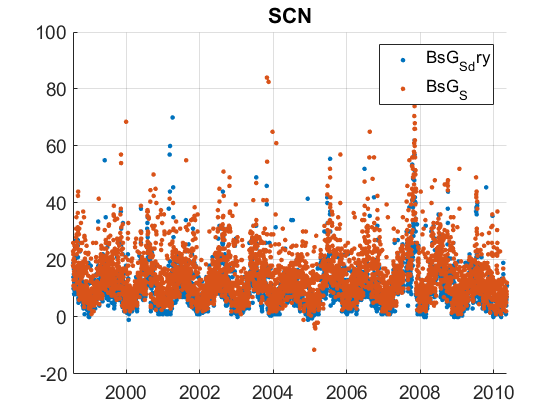

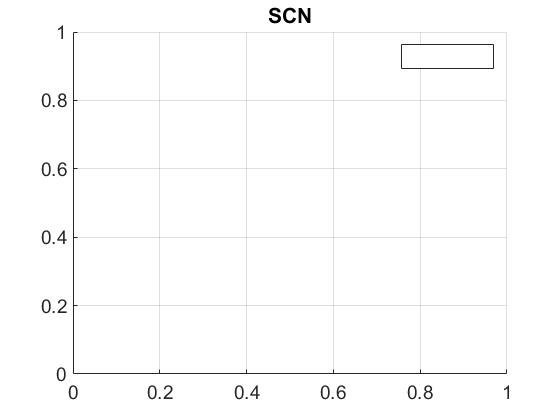

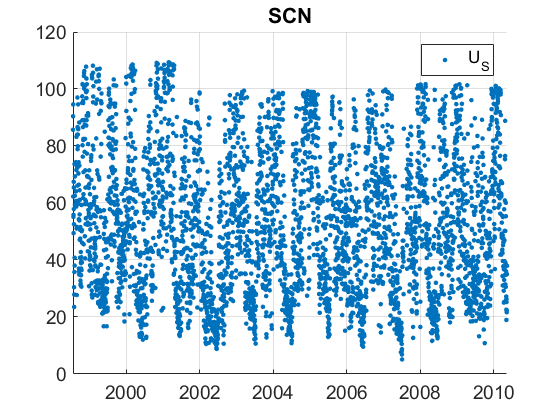

plotFigControl(SCN_rd,SCN_st.name);

% 1 size cut, 
% sc: ok, clear seasonal cycle, max in summer-autumn, some negatives


%Questions:
%problems:

SCN_tr=SCN_rd;
SCN_tr.y=year(SCN_tr.Time);

% begin at the beginning of a year:1999
%end year: 2009
P=timerange('1999-01-01','2010-01-01');
SCN_tr=SCN_tr(P,:);

names=fieldnames(SCN_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    SCN_tr.(N{i})=[];
end
% dry: OK
%otherwise seems ok

SCN_result= all_trend_STN(SCN_tr,SCN_st); 


SCN_result_D=SCN_result;

